% Initialize Robot using Modified DH
clear
close all
syms theta1 theta2 theta3;
l1 = 0.35;
d2= 0.4605;
l2 = 0.25;
d3_offset = 0.0855;
% Modified DH parameters
L(1) = Link([0,0,0,0,0],'modified');
L(2) = Link([0,d2,l1,0,0],'modified');
L(3) = Link([0,0,l2,pi,1],'modified');
L(4) = Link([0,0,0,0,0],'modified');
L(3).qlim = [0,0.6];
L(3).offset = d3_offset;
% Center of mass
L(1).r = [0.18, 0, -0.04];
L(2).r = [0.12, 0, 0.24];
L(3).r = [0, 0, -0.3];
L(4).r = [0, 0, 0];
% Mass
L(1).m = 10;
L(2).m = 30;
L(3).m = 2;
L(4).m = 0.5;
% Inertia
L(1).I = [0.02, 0, 0; 0, 0.21, 0; 0, 0, 0.23];
L(2).I = [0.27, 0, 0; 0, 0.61, 0; 0, 0, 0.43];
L(3).I = [0.06, 0, 0; 0, 0.06, 0; 0, 0, 0.00];
L(4).I = [0.0005, 0, 0; 0, 0.0005, 0; 0, 0, 0.0002]; % suppose r = 0.03, h = 0.1
% Motor inertia
L(1).Jm = 0.001;
L(2).Jm = 0.001;
L(3).Jm = 0.001;
L(4).Jm = 0.001;
% Motor friction
L(1).B = 0.0001;
L(2).B = 0.0001;
L(3).B = 0.0001;
L(4).B = 0.0001;
% Gear ratio
L(1).G = 10;
L(2).G = 10;
L(3).G = 10;
L(4).G = 10;
Robot1 = SerialLink(L,'name','Asgmt-SCARA-SRX611');
Robot1.display();

 
Robot1 = 
 
Asgmt-SCARA-SRX611:: 4 axis, RRPR, modDH, slowRNE                
+---+-----------+-----------+-----------+-----------+-----------+
| j |     theta |         d |         a |     alpha |    offset |
+---+-----------+-----------+-----------+-----------+-----------+
|  1|         q1|          0|          0|          0|          0|
|  2|         q2|     0.4605|       0.35|          0|          0|
|  3|          0|         q3|       0.25|    3.14159|     0.0855|
|  4|         q4|          0|          0|          0|          0|
+---+-----------+-----------+-----------+-----------+-----------+
 


% Inverse Kinematics: using @myikine
T0 = [1,0,0,0.6; 0,-1,0,0;0,0,-1,0.375;0,0,0,1];
T1 = [1,0,0,0.175; 0,-1,0,0.5531; 0,0,-1, 0.075; 0,0,0,1];
Q0 = Robot1.ikine(T0,'mask',[1,1,1,0,0,1]);
Q1 = Robot1.ikine(T1,'mask',[1,1,1,0,0,1]);
% Q0 = myikine(T0);
% Q1 = myikine(T1);
% Q0 = Q0(1,:);
% Q1 = Q1(1,:);

% Trajectory generation: @jtraj (joint space)
T_total = 2;
T_int = 0.1;
[Q_star, Qd_star, Qdd_star] = jtraj(Q0, Q1, 0:T_int:T_total);

% Trajectory generation: Cartesian straight-line
T_total = 2;
T_int = 0.1;
Ts = ctraj(T0, T1, T_total/T_int + 1);
Q_star = Robot1.ikine(Ts, 'mask', [1, 1, 1, 0, 0, 1]);
% interpolation
interT = 0.001;
Q_star_int = interp1(0:T_int:T_total,Q_star,0:interT:T_total,'spline');
Qd_star = [gradient(Q_star_int(:,1))./interT, gradient(Q_star_int(:,2))./interT, gradient(Q_star_int(:,3))./interT, gradient(Q_star_int(:,4))./interT];
Qdd_star = [gradient(Qd_star(:,1))./interT, gradient(Qd_star(:,2))./interT, gradient(Qd_star(:,3))./interT, gradient(Qd_star(:,4))./interT];
% final Qd_star & Qdd_star
Qd_star = interp1(0:interT:T_total,Qd_star,0:T_int:T_total,'linear');
Qdd_star = interp1(0:interT:T_total,Qdd_star,0:T_int:T_total,'linear');

% Simulation: Computed Torque control (SerialLink.fdyn)
sizeQ = size(Q_star);
T = [0];
Q = [0, 0, 0, 0];
%Qd = [0, 0, 0, 0];
q = [0, 0, 0, 0];
qd = [0, 0, 0, 0];
for i = 2:sizeQ(1)
    sizeq = size(q);
    sizeqd = size(qd);
    [t, q, qd] = Robot1.nofriction().fdyn(T_int, @ctorqfun, q(sizeq(1), :), qd(sizeqd(1), :), Q_star(i,:), Qd_star(i,:), Qdd_star(i,:), 40, 13);
    T = [T; T(length(T))+t];
    Q = [Q; q];
    %Qd = [Qd; qd];
end
Q_star1 = interp1q(linspace(0, T_total, length(Q_star))', Q_star, T);
err = Q_star1 - Q;

% Simulation: Individual-joint PID control (Simulink + RTB.roblocks)
N = T_total/T_int;
a.time = T_int*[0:N]';
a.signals(1).values = Q_star;
a.signals(1).dimensions = 4;
simOut = sim("PIDctrl.slx", [0,T_total]);
T = simOut.t;
Q = simOut.y(:,1:4);
err = simOut.y(:,5:8);

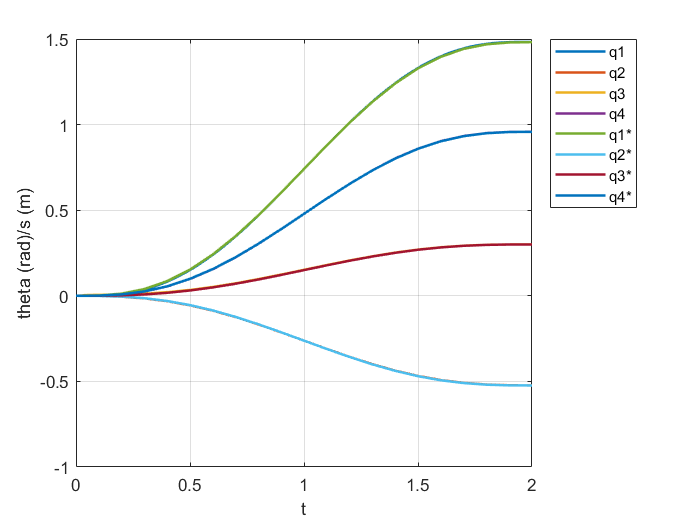

% Visualization
figure(1)
plot(T, Q, linspace(0, T_total, length(Q_star)), Q_star,'LineWidth',1.5);
xlabel('t');
ylabel('theta (rad)/s (m)');
xlim([0 T_total]);
legend('q1','q2','q3','q4','q1*','q2*','q3*','q4*','Location','bestoutside')
grid on;

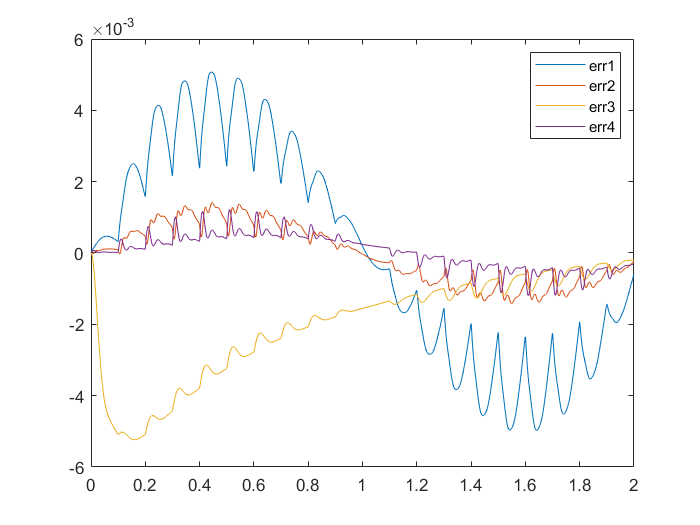

figure(2)
plot(T,err);
legend('err1','err2','err3','err4')

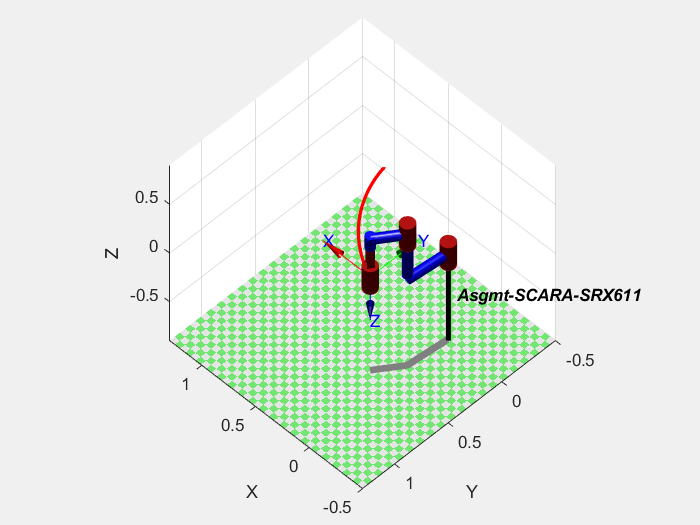

Animate: saving video --> file.mp4 with profile 'MPEG-4'


figure(3)
plotint = 0.01;
stdQt = interp1q(T,Q,(0:plotint:T_total)'); 
% linear interpolation before using SerialLink.plot
Robot1.plot(stdQt, 'workspace', [-0.5,1.3,-0.5,1.3,-0.9,0.9], 'fps', 200, 'trail', {'r', 'LineWidth', 2}, 'zoom', 1.5, 'movie','file.mp4','view',[225,50])

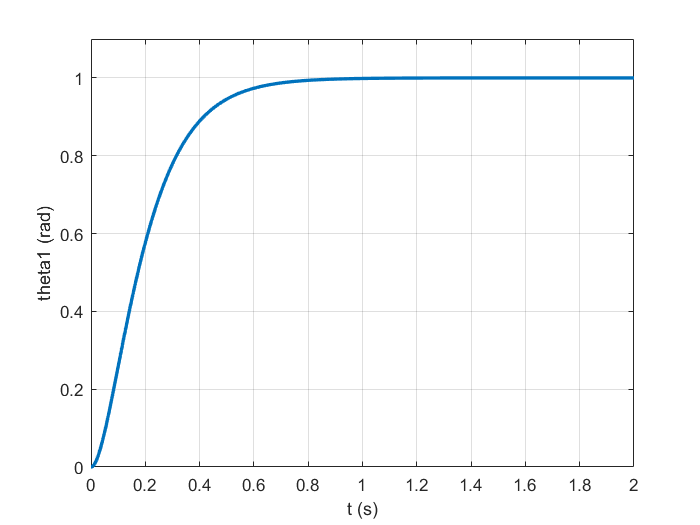

% Test: control system respose (computed torque)
[t,q,qd] = Robot1.nofriction().fdyn(2, @ctorqfun,[0, 0, 0, 0], [0, 0, 0, 0], [1, 1, 0, 1], [0, 0, 0, 0], [0, 0, 0, 0], 100, 21);
%Robot1.plot(q)
plot(t,q(:,1),'LineWidth',2);
xlabel('t (s)')
ylabel('theta1 (rad)')
grid on;
ylim([0 1.1]);

% Solve for Transformation matrix
syms theta1 theta2 d3 theta4 l1 l2 d2 d_3offset
L(1) = Link([0,0,0,0,0],'modified');
L(2) = Link([0,d2,l1,0,0],'modified');
L(3) = Link([0,0,l2,sym(pi),1],'modified');
L(4) = Link([0,0,0,0,0],'modified');
L(3).offset = d_3offset;
Robot2 = SerialLink(L,'name','Asgmt-Tsolve');
T = Robot2.A(1:4, [theta1 theta2 d3 theta4]);
simplify(T)

$$\left(\begin{array}{cccc} \cos\left(\theta_{1}+\theta_{2}-\theta_{4}\right) & \sin\left(\theta_{1}+\theta_{2}-\theta_{4}\right) & 0 & l_{2}\,\cos\left(\theta_{1}+\theta_{2}\right)+l_{1}\,\cos\left(\theta_{1}\right)\\ \sin\left(\theta_{1}+\theta_{2}-\theta_{4}\right) & -\cos\left(\theta_{1}+\theta_{2}-\theta_{4}\right) & 0 & l_{2}\,\sin\left(\theta_{1}+\theta_{2}\right)+l_{1}\,\sin\left(\theta_{1}\right)\\ 0 & 0 & -1 & d_{2}-d_{3}-d_{\mathrm{3offset}}\\ 0 & 0 & 0 & 1 \end{array}\right)$$